%This Matlab script is the main of the article:
%
% Andrea Pizzo, Daniel Verenzuela, Luca Sanguinetti and Emil Bj繹rnson, "Network Deployment for Maximal Energy Efficiency 
% in Uplink with Multislope Path Loss," IEEE Transactions on Green Communications and Networking, Submitted to.
%
%This is version 1.0 (Last edited: 10-April-2018)
%
%License: This code is licensed under the GPLv2 license. If you in any way
%use this code for research that results in publications, please cite our
%original article listed above.
%
%
%This script compute the lower bound on the average ergodic spectral
%efficiency as in Theorem 2 (Section 3) of the article cited above. 
%This is achieved by calling 3 functions: 
%functionExampleSetup, functionChannelEstimates and functionComputeSE_UL. The function "functionExampleSetup" 
%deploys the UEs and the BSs randomly wihin the coverage area as described
%in Section 2. The function "functionChannelEstimates" computes all the
%uplink channel estimate for all UEs in the entire network. The function
%"functionComputeSE_UL" uses the true channel and the channel estimates to
%compute the uplink average ergodic spectral efficiency.


%Empty workspace and close figures
close all;
clear;
clc;

%Number of UEs per BS
K = 10;

%Define the range of BS antennas
Mrange = [50 100 150 200];

%Extract maximum number of BS antennas
Mmax = max(Mrange);

%Define the average pilot reuse factor
fRange = 1:1:4; 

%Select the number of setups with random UE locations
nbrOfSetups = 1;

%Select the number of channel realizations per setup
nbrOfRealizations = 1;

% Generates BS locations over (1) a fixed grid or
% (2) as a Homogeneous Poisson Point Process H-PPP
deployment = 2;

%在這段程式碼中，deployment 變數用來決定基地台的部署方式，有兩種選擇：
%固定網格（Fixed Grid）：
%當 deployment 變數的值為 1 時，表示基底站在一個固定的網格上進行部署。 這意味著基地台的位置被預先確定，並且通常以規則的網格狀方式分佈在所選區域內。
%均勻泊松點過程（Homogeneous Poisson Point Process，H-PPP）：

%當 deployment 變數的值為 2 時，表示基地台依照均勻泊松點程序進行部署。 在這種部署方式下，基地台的位置是隨機的，並且遵循泊松點過程的統計特性，即在給定區域內的任意位置的基地台數量服從泊松分佈。
%根據模擬的需要和實際情況，可以選擇合適的基地台部署方式。 固定網格適用於需要控制基地台位置並具有規律性的場景，而H-PPP適用於更真實和隨機的場景。


% Generates the large scale path-loss coefficient using (1) single slope or
% (2) multi slope model
pathloss = 2;

% (1) Correlated or (2) Uncorellated channel fading
c = 2;

% Density of BSs for the random deployment
lambdaRange = fliplr([1 2:2:8]);

%這段程式碼是用來定義隨機部署中基站（BS）的密度。在這個情境下，`lambdaRange` 是一個向量，它包含了不同的基站密度值，這些值會在仿真中使用。
%在這個特定的例子中，`fliplr([1 2:2:2])` 的意思是建立一個向量，該向量包含了從 1 開始的奇數數列 `[1 3 5 ...]`，然後使用 `fliplr` 函式將這個向量反轉，所以最後的 `lambdaRange` 就變成了 `[1 1 1]`。
%這表示在這個仿真中，基站密度是固定的且為 1，即每平方公里有一個基站。這樣的設置可能用於在密集型網絡下進行效能評估，其中每個基站的服務範圍被合理地重疊，以提供充足的覆蓋和容量。

% Check the lengths of the variables
disp(length(lambdaRange));

     5



disp(length(fRange));

     4



disp(length(Mrange));

     4




%Load fixed Propagation parameters
SetPropagationParameters;

%這段是呼叫SetPropagationParameters這隻程式碼
%%

%Prepare to save simulation results
sumSE_MR = zeros(length(lambdaRange),length(fRange),length(Mrange),nbrOfSetups);
sumSE_ZF = zeros(length(lambdaRange),length(fRange),length(Mrange),nbrOfSetups);
sumSE_RZF = zeros(length(lambdaRange),length(fRange),length(Mrange),nbrOfSetups);
sumSE_SMMSE = zeros(length(lambdaRange),length(fRange),length(Mrange),nbrOfSetups);
sumSE_MMMSE = zeros(length(lambdaRange),length(fRange),length(Mrange),nbrOfSetups);

%這段程式碼保存到Allen_simulation中
% Check the dimensions of the variables
disp(size(sumSE_MMMSE));

     5     4     4



disp(size(sumSE_SMMSE));

     5     4     4



disp(size(sumSE_RZF));

     5     4     4



disp(size(sumSE_ZF));

     5     4     4



disp(size(sumSE_MR));

     5     4     4



%% Go through all lambda values
for ll = 1:length(lambdaRange)
    
    %Output simulation progress
    disp([num2str(ll) ' lambda values out of ' num2str(length(lambdaRange))]);
    
% 這段 MATLAB 代?使用了一個 for 循環來遍歷 lambdaRange 向量,並輸出當前的模擬進度。允許我為您詳細解釋:
%1. for ll = 1:length(lambdaRange) 定義了一個循還,變量 ll 從 1 迭代到 lambdaRange 的長度。
%2. 在每次迭代中,ll 對應 lambdaRange 中的一個基站密度值。
%3. disp() 用於在 MATLAB 命令視窗輸出信息。
%4. num2str() 函數可以把數字轉換為字符串。
%5. \[\] 用於字符串連接,實現類似字符串格式化的效果。
%6. 輸出的字符串代表當前是第 ll 個 lambda 值,總共有 length(lambdaRange) 個。
%整體意思就是,在循環迭代 lambdaRange 中每一個基站密度時,輸出當前的模擬進度。這樣可以方便追蹤長時間運行的模擬實驗的進展情況。
%這種 Simple 的進度輸出在長時間運行的實驗中是非常有用的,既可以查看當前狀態,也可以估計剩余時間。總體上很好地體現了 MATLAB 在工程應用上輸出信息和傳達狀態的便利性。
    % Go through all setups
    for n = 1:nbrOfSetups
        
        %Output simulation progress
        disp([num2str(n) ' setups out of ' num2str(nbrOfSetups)]);
        
        if deployment  == 1
            
            L = 16;
            
        elseif deployment == 2
            
            %Generate the number of BSs in the area per km^2
            L = round(poissrnd(lambdaRange(ll)*(squareLength/1000)^2));
            
            %If the number is zero, then make a new realization
            while L == 0
                L = round(poissrnd(lambdaRange(ll)*(squareLength/1000)^2));
            end
    
        end
        
        %Compute channel statistics for one setup
        [R,channelGaindB] = functionExampleSetup(L,K,Mmax,accuracy,ASDdeg,squareLength,Pathloss_model,deployment,pathloss);
        
        %Compute the normalized average channel gain, where the normalization
        %is based on the noise power
        channelGainOverNoiseOriginal = channelGaindB - noiseVariancedBm;
        
        %Extract the average channel gains before power control
        channelGainOverNoise = channelGainOverNoiseOriginal;
        
        %Go through all cells
        for j = 1:L
            
            %Scale the average channel gains by applying the inverse statistical power control
            backoff = channelGainOverNoiseOriginal(:,j,j) + 10*log10(p) - DeltadB;
            channelGainOverNoise(:,j,:) = channelGainOverNoiseOriginal(:,j,:) - repmat(backoff,[1 1 L]);
            
        end
                
        %Go through all number of antennas
        for m = 1:length(Mrange)
            
            %Output simulation progress
%             disp([num2str(m) ' antennas out of ' num2str(length(Mrange))]);
            
            %Go through all pilot reuse factors
            for s = 1:length(fRange)
                
                %Extract pilot reuse factor
                f = fRange(s);
                
                if c == 1 %Correlated fading
                    
                    %Generate channel realizations with estimates and estimation
                    %error correlation matrices
                    disp('Running for correlated fading');
                    [Hhat,C,tau_p,Rscaled] = functionChannelEstimates(R(1:Mrange(m),1:Mrange(m),:,:,:),channelGainOverNoiseOriginal,nbrOfRealizations,Mrange(m),K,L,p,f,deployment);
                    
                elseif c == 2 %Uncorrelated fading
                    
                    %Generate uncorrelated correlation matrices
                    Runcorr = repmat(eye(Mrange(m)),[1 1 K L L]);
                    
                    %Generate channel realizations with estimates and estimation
                    %error correlation matrices
                    disp('Running for uncorrelated fading');
                    [Hhat,C,tau_p,Rscaled] = functionChannelEstimates(Runcorr,channelGainOverNoise,DeltadB_pilot,nbrOfRealizations,Mrange(m),K,L,p,f,deployment);
                    
                end

                %Compute SEs using Theorem 4.1
                [SE_MR,SE_RZF,SE_MMMSE,SE_ZF,SE_SMMSE] = functionComputeSE_UL(Hhat,C,Rscaled,tau_c,tau_p,nbrOfRealizations,Mrange(m),K,L,p);

                %Save average sum SE per cell
                sumSE_MR(ll,s,m,n) = mean(sum(SE_MR,1));
                sumSE_ZF(ll,s,m,n) = mean(sum(SE_ZF,1));
                sumSE_SMMSE(ll,s,m,n) = mean(sum(SE_SMMSE,1));
                sumSE_RZF(ll,s,m,n) = mean(sum(SE_RZF,1));
                sumSE_MMMSE(ll,s,m,n) = mean(sum(SE_MMMSE,1));
                
                %Delete large matrices
                clear Hhat C Rscaled;
                
            end
            
        end
        
        %Delete large matrices
        clear R;
        
    end
    
        save('../SimulationResults/Allen_simulation','deployment','pathloss','c','DeltadB','DeltadB_pilot','Pathloss_model','lambdaRange','fRange','Mrange','K','sumSE_MR','sumSE_ZF','sumSE_RZF','sumSE_SMMSE','sumSE_MMMSE','SE_MR','SE_RZF','SE_MMMSE','SE_ZF','SE_SMMSE');

end

1 lambda values out of 5


1 setups out of 1


Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading


2 lambda values out of 5


1 setups out of 1


Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading


3 lambda values out of 5


1 setups out of 1


Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading


4 lambda values out of 5


1 setups out of 1


Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading


5 lambda values out of 5


1 setups out of 1


Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading
Running for uncorrelated fading


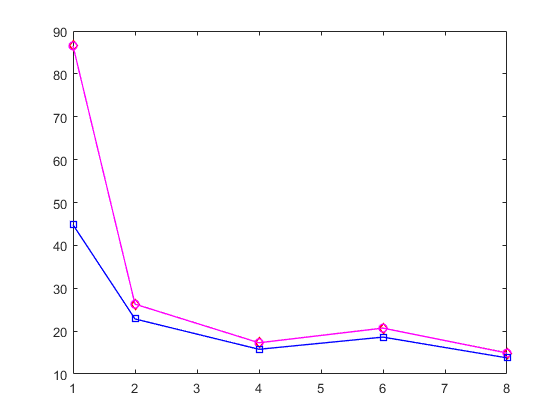

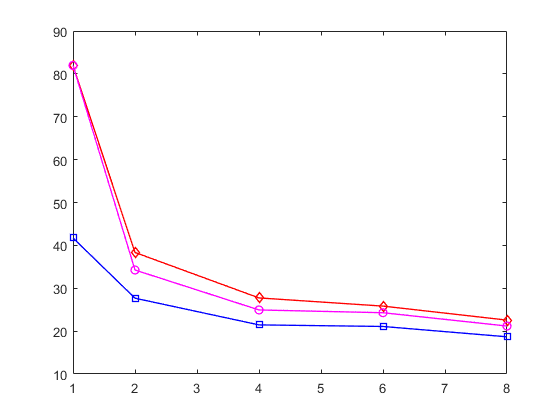

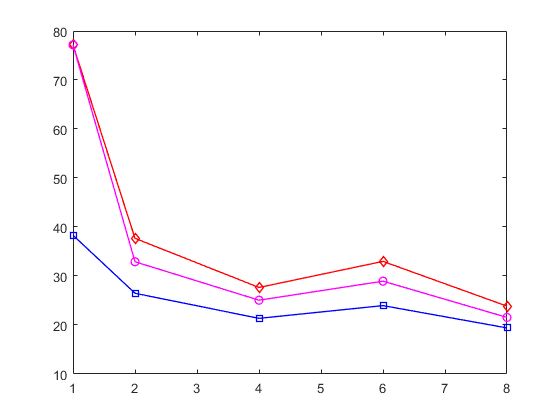

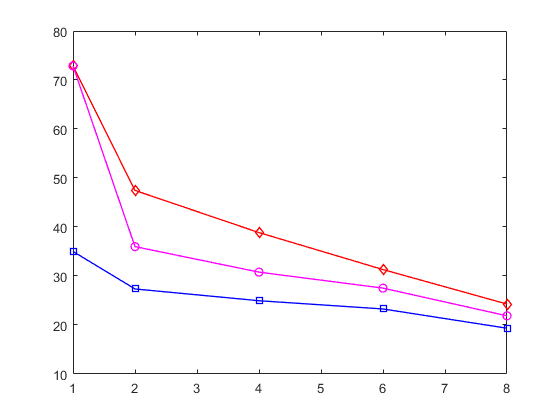


 %% Plot the simulation results
 mm = length(Mrange);

 %Plot aggregate SE per cell vs BS density
 for ff = 1:length(fRange)
    
     figure(length(lambdaRange)+ff);
     hold on; box on;
     plot(lambdaRange,squeeze(mean(sumSE_MMMSE(:,ff,mm,:),4)),'rd-','LineWidth',1);
     plot(lambdaRange,squeeze(mean(sumSE_SMMSE(:,ff,mm,:),4)),'b:','LineWidth',1);
     plot(lambdaRange,squeeze(mean(sumSE_RZF(:,ff,mm,:),4)),'k-.','LineWidth',1);
     plot(lambdaRange,squeeze(mean(sumSE_ZF(:,ff,mm,:),4)),'mo-','LineWidth',1);
     plot(lambdaRange,squeeze(mean(sumSE_MR(:,ff,mm,:),4)),'bs-','LineWidth',1);   
 end